# Tuning PID Controllers via Genetic Algorithms

The following code serves as the "main file" for implementing a Genetic Algorithm (GA) for tuning a PID controller.  

## DC Servomotor Response without any Controller

Before begining, recall that the closed-loop system response of the DC motor without any controller scheme appears accordingly below. 

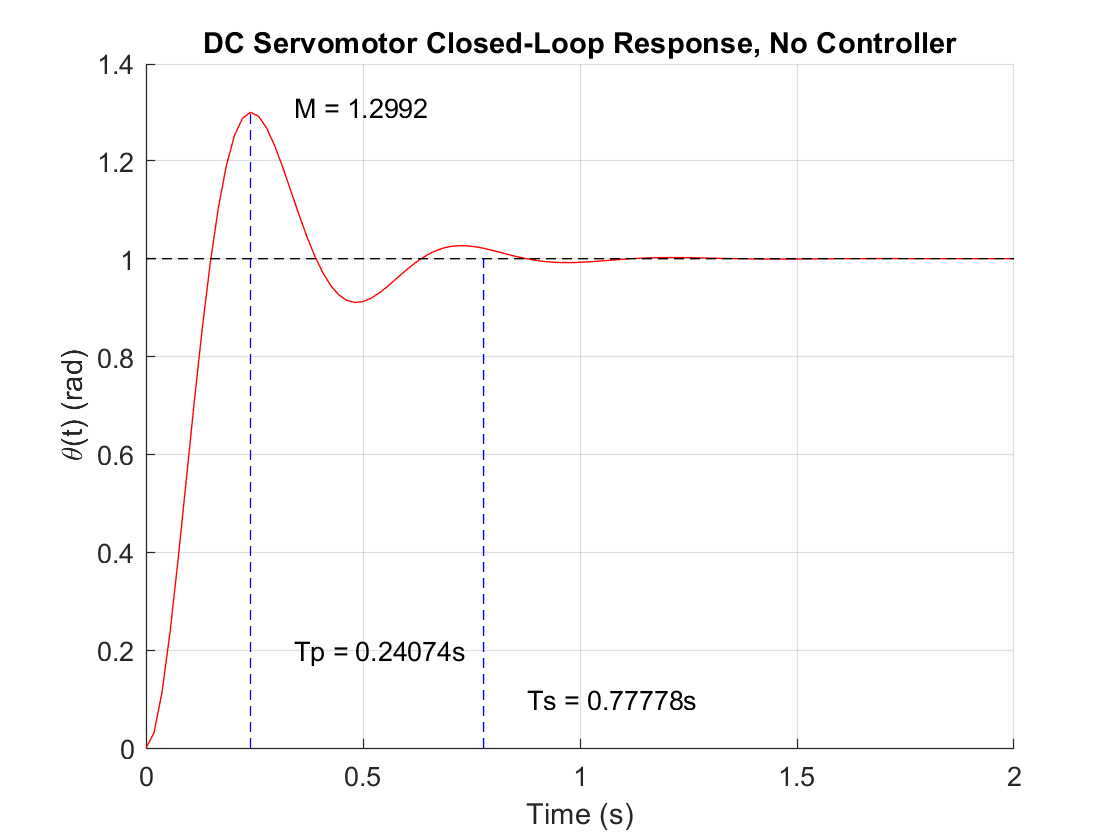

% DC Servomotor closed-loop response, no controller
[M, Tp, Ts] = PID_controller_sim(1, 0, 0, 1);
title('DC Servomotor Closed-Loop Response, No Controller')

## Define the Parameters and Initialize the GA

This section serves as the entry fields for the GA algorithm.  Once all the parameters have been entered, the GA is initialized.  The population structure is built, and the first generation is processed.  

#### Starting Fresh

Clearing out any unrelated open figures as well as the workspace.  Additionally, the random number generator (rng) is seeded to the same value in every run.  This is for debugging purposes, as analyzing the same random operations makes debugging much easier.  Seeding the RNG should be removed once the program is fully operational.  

% Start Fresh
close all
clear 

% reset random number generator (easier to debug when the same random operations occur)
rng(10);


#### Define the Desired DC Servomotor Response Characteristics

In this section we define the DC Servomotor response characteristics we wish to have.  In this case, we can specify the desired overshoot, peak time, and settling time.  These desired values are entered as a vector, and should be entered in the following format.  

                                                                    
$$\textrm{specs}=\left\lbrack M,\;T_p ,{\;T}_s \right\rbrack$$


% Define Specifications for DC Servomotor Response Characteristics [M, Tp, Ts]
specs = [1.2, 0.2, 0.3];


#### Define the Parameters of the Genetic Algorithm (GA)

Here is where the settings of the Genetic Algorithm (GA) can be adjusted.  By adjusting these settings, we can allow for finding the optimal solution in an uncertian solution space.  

pop_size - the population size in a given generation

max_gen - the number of generations that will be processed in the algorithm

num_chrom - the number of chromosomes each individual has  ***This setting should stay fixed for the problem at hand ***

pcross - the probability of a crossover operation occuring

pmutate - the probability of an allele mutating

kX_options - the options for encoding a certian gain chromosome where "X" could be "p, i, or d".  Since all gains will be positive, the option format reads as: [the highest number to represent, the number of bits to represent the number]  The bit string reads as a decimal fraction encoding a value between zero and one.  For example, the setting provided as [hi, N] would be decoded as:

                                            
$$k_X \;=\;\textrm{hi}\cdot \left\lbrack b_1 2^{-1} +b_2 2^{-2} +b_3 2^{-3} +\ldotp \ldotp \ldotp +b_N 2^{-N} \right\rbrack$$

$$\textrm{where}\;b_n \;\textrm{refers}\;\textrm{to}\;\textrm{an}\;\textrm{allele}\;\textrm{in}\;\textrm{the}\;\textrm{chromosome}$$


controller - the controller scheme to be employed.  This setting should be entered as a string.  The two options are "PID" and "PIwRFB" as entries for the settings.  

                  PID - proportional integral derivative (PID) controller

                  PIwRFB - proportional integral controller with rate-feedback


% Define Parameters of the GA
pop_size = 15;
max_gen = 30;
num_chrom = 3; % Do Not Adjust
pcross = 0.75; 
pmutate = 0.08;
kp_options = [2, 30];
ki_options = [1, 25];
kd_options = [0.1, 20];
controller = "PID";


#### Optional: Elitism Settings

Elitism refers to protecting the "fittest" individuals and a population from crossover and mutation operations as each generation advances.  Implementing this approach is optional, and its settings can be adjusting accordingly below.

elistism_flag - set to 1 to implement elistism.  set to 0 to turn it off

num_elite - the number of individuals in a generation you wish to protect from crossover and mutation operations

% Optional:  Elitism Settings
elitism_flag = 0;
num_elite = 3;


#### Initialize the GA

All the settings defined above as passed into the function 'ga_init' to build the population structure.  By employing this algorithm as a structure, passing data in and out of functions becomes a simple process.  

Once all the settings are initialized, the first generation is build, processed, and analyized.  

% Initialize the GA structure
pop = ga_init(pop_size, max_gen, num_chrom, pcross, pmutate, specs, ...
              kp_options, ki_options, kd_options, controller, elitism_flag, num_elite);

## Process each Generation

After the first generation has been processed in the function 'ga_init', the generations evolve.  In each iteration, the following occurs:

 - Two mates are selected at random.  Individuals with a higher fitness score are more likely to be selected.

 - Crossover operations occur between the two mates.  This simulates the "mating" of the two individuals.

 - Mutation operations occur to both mates

 - Fitness values are assessed for each member of generation, and the statistics are collected to determine GA performance

See the documentation of the function 'advance_one_generation' for more information.   

% For each desired iteration of a generation
for ii = 1 : max_gen-1
    
    % Advance One Generation
    pop(ii+1) = advance_one_generation(pop, ii);
    
end

## Find the Winner

Given the nature of this random search, the individual among all the generations with the highest fitness score is located.  This individual represents the best gain combination which matches our desired specifications.  

% Locate the Winner among all the generations
[~, winning_gen] = max([pop(:).maxfitness]);
[winning_score, winning_indiv] = max(pop(winning_gen).fitness_vect);


#### How well did the winner perform?

Below shows the response created by the winning gain combination.  Ideally, this will match very closely with the desired specifications.  

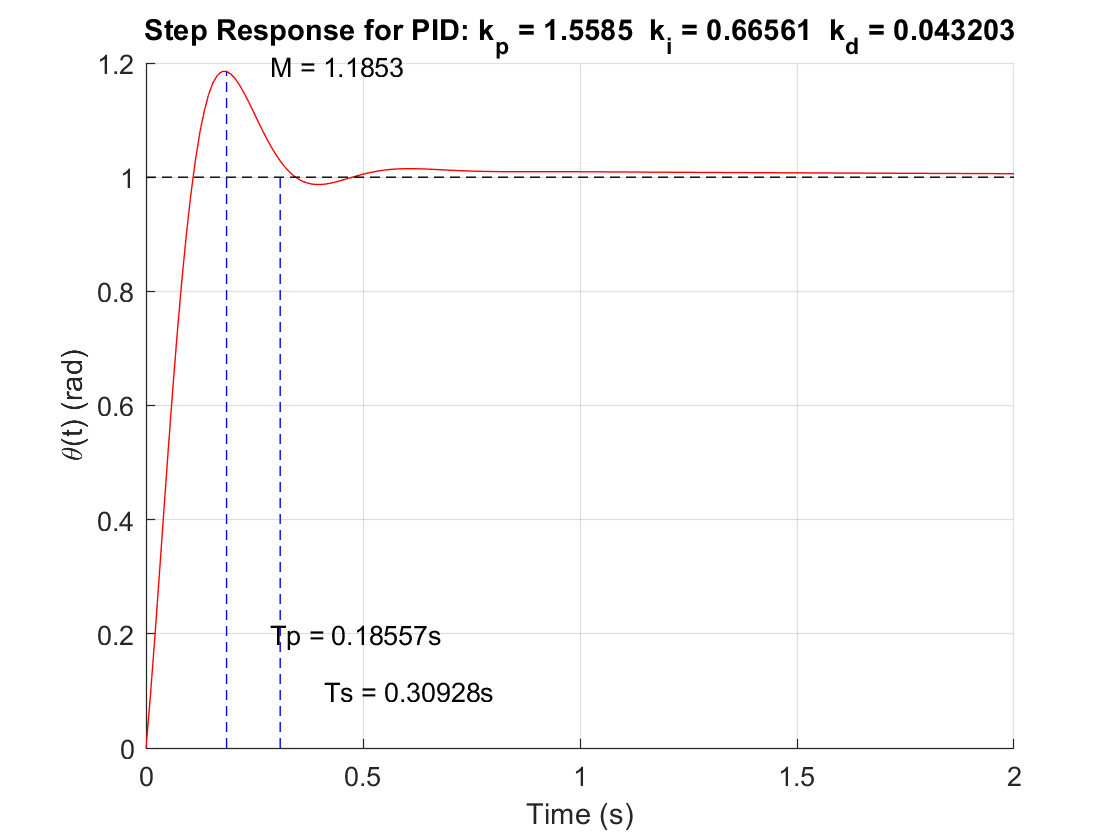

% Let the winner show off their skills
kp = pop(winning_gen).indiv(winning_indiv).gains(1);
ki = pop(winning_gen).indiv(winning_indiv).gains(2);
kd = pop(winning_gen).indiv(winning_indiv).gains(3);

if (controller == "PID")
    [M, Tp, Ts] = PID_controller_sim(kp, ki, kd, 1);
elseif (controller == "PIwRFB")
    [M, Tp, Ts] = PIwRFB_controller_sim(kp, ki, kd, 1);
end

#### Performance, by the numbers

Below shows a table indicating the desired specifications, the resulting performance, and the percentage error from these desired specifications.  

% Calculating Percentage Error
PE_M = 100 * ((M - specs(1))/specs(1));
PE_Tp = 100 * ((Tp - specs(2))/specs(2));
PE_Ts = 100 * ((Ts - specs(3))/specs(3));
tab = [specs; [M Tp Ts]; [PE_M, PE_Tp, PE_Ts]];
row_names = {'Desired Specs', 'Obtained Performance', 'Percent Error'};
column_names = {'Overshoot (ratio)', 'Peak Time (s)', 'Settling Time (s)'};
T = array2table(tab, 'RowNames', row_names, 'VariableNames', column_names)

T = 3×3 table
                            Overshoot (ratio)    Peak Time (s)    Settling Time (s)
                            _________________    _____________    _________________

    Desired Specs                    1.2                0.2                0.3     
    Obtained Performance          1.1853            0.18557            0.30928     
    Percent Error                -1.2261            -7.2165             3.0928     


## Performance of the GA itself

It is dificult to show exactly how well the GA performed when the optimal solution itself is unknown.  We can however, look how the generations evolved from one to the next.  Ideally, we should see all three trackers, the max fitness score in a generation, the average fitness score in a generation, and the minimum fitness score of a generation, all slowly increase throughout its progression.  Given that all of this occurs at random, there may not be much to witness.  

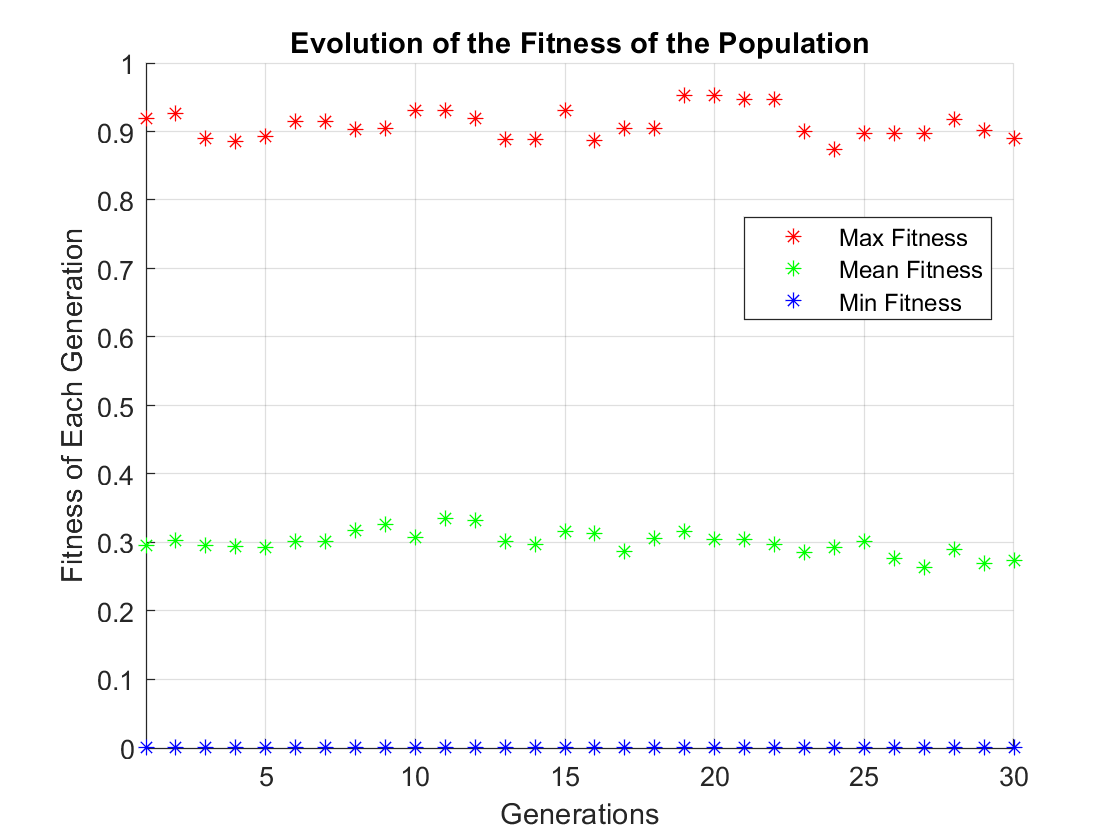

% Plot Results
n = 1 : max_gen;

figure
hold on
plot(n, [pop(:).maxfitness], 'r*')
plot(n, [pop(:).avefitness], 'g*')
plot(n, [pop(:).minfitness], 'b*')
title('Evolution of the Fitness of the Population')
xlabel('Generations')
xlim([1 max_gen])
ylabel('Fitness of Each Generation')
ylim([0 1])
grid on
legend('Max Fitness', 'Mean Fitness', 'Min Fitness', 'Location', 'Best')
hold off